savedir = '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/bag/DataSet1/PosPortion1.mat';
bag = block_bag.loadProperties(savedir);

Error using load
Unable to read file '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/bag/DateSet1/PosPortion1.mat'. No such file or directory.

Error in block_bag.loadProperties (line 160)
            bag = load(savedir);

Scheme = '';
GenParam = '';
mdl1 = block_mdl({'Scheme',Scheme,'GenParam',GenParam});

Model Default: SVM


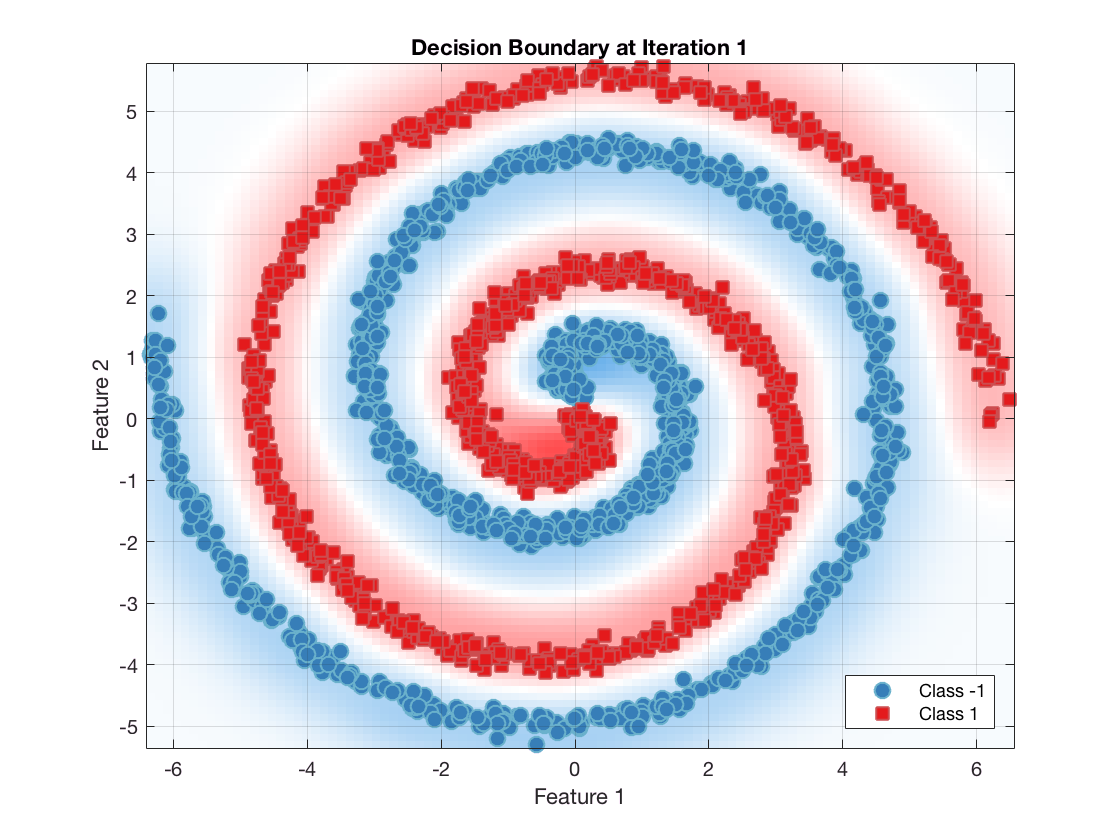

Scheme = 1;
GenParam.Random = 0;
GenParam.Percent = 1;
GenParam.MaxIter = 20;
GenParam.KernelSize = 1;
GenParam.Solver = 'SMO';
mdl2 = block_mdl({'Scheme',Scheme,'GenParam',GenParam});
mdl2 = mdl2.run(bag);
% picsavedir = '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/mdl/'
mdl2.PlotDecBound();

block_mdl.saveProperties(mdl2);

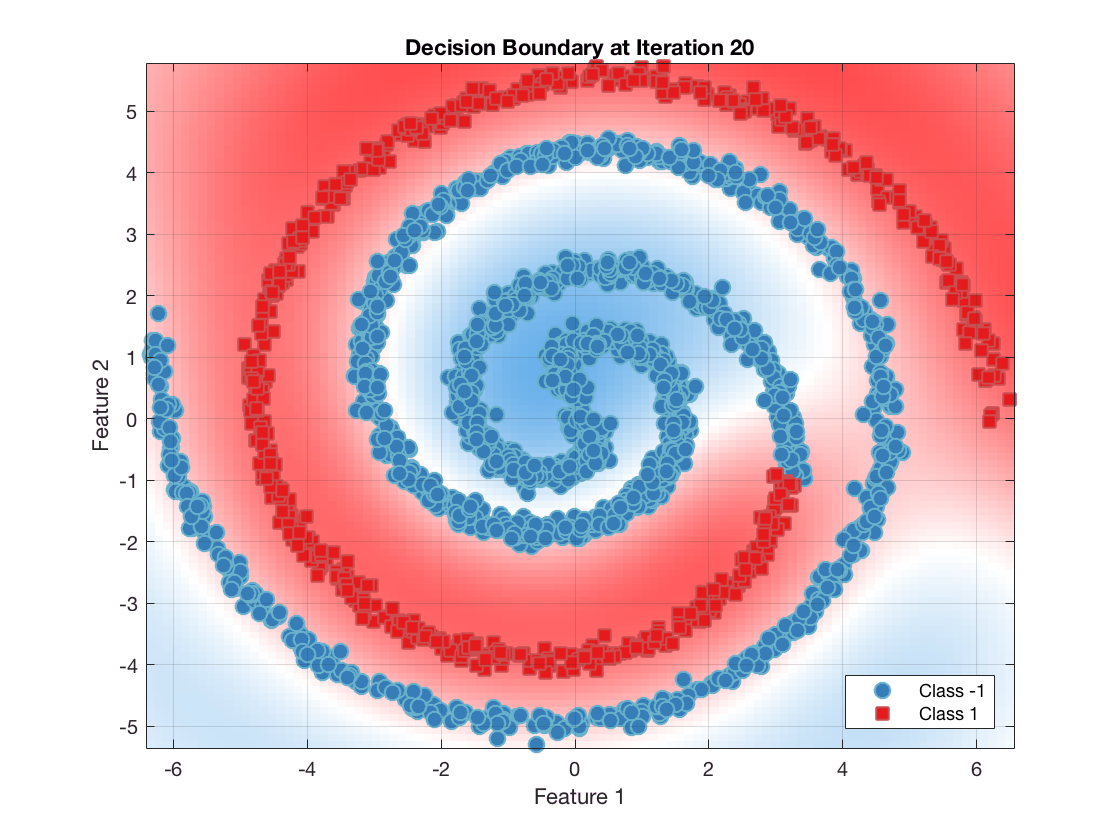

Scheme = 1;
GenParam.Random = 0;
GenParam.Percent = 1;
GenParam.MaxIter = 20;
GenParam.KernelSize = 3;
GenParam.Solver = 'SMO';
mdl3 = block_mdl({'Scheme',Scheme,'GenParam',GenParam});
mdl3 = mdl3.run(bag);
mdl3.PlotDecBound();

block_mdl.saveProperties(mdl3);

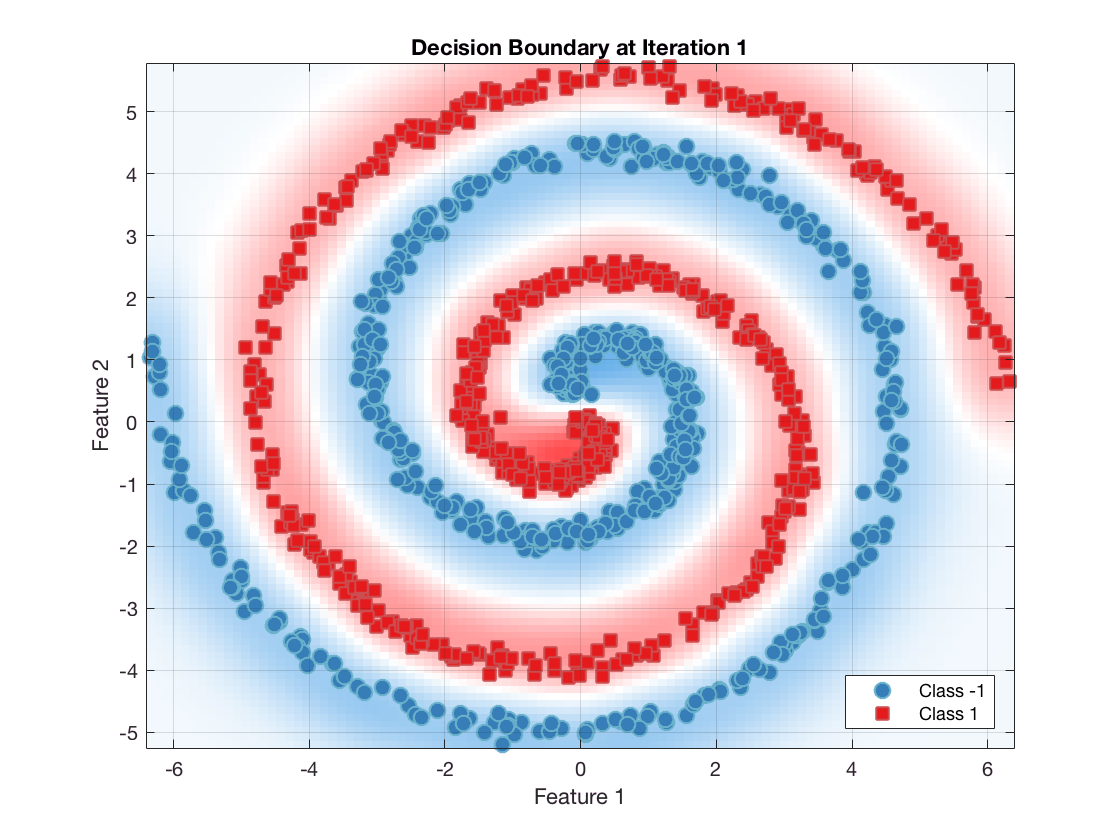

Scheme = 1;
GenParam.Random = 0;
GenParam.Percent = 0.5;
GenParam.MaxIter = 20;
GenParam.KernelSize = 1;
GenParam.Solver = 'SMO';
mdl4 = block_mdl({'Scheme',Scheme,'GenParam',GenParam});
mdl4 = mdl4.run(bag);
% picsavedir = '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/mdl/'
mdl4.PlotDecBound();

block_mdl.saveProperties(mdl4);

Scheme = 2;
GenParam.Random = 0;
GenParam.Percent = 0.5;
GenParam.MaxIter = 20;
GenParam.KernelSize = 3;
GenParam.Solver = 'SMO';
GenParam.Threshold = 1;
GenParam.Step = 0.5;
mdl5 = block_mdl({'Scheme',Scheme,'GenParam',GenParam});
mdl5 = mdl5.run(bag);
% picsavedir = '/Users/yueweiyang/Documents/study/duke/independent study/fall 2017/matlab/multiple instance learning/result/mdl/'
mdl5.PlotDecBound();

block_mdl.saveProperties(mdl5);